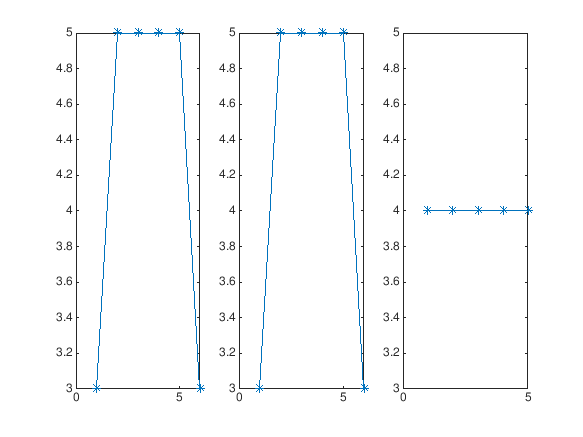

%% VARIBLE DEFINITIONtS
% check also for loop_count in addition & repair phase
% check for allowing connectivity among same side as well (overcome spare connectivity loss)
% ** update of simulate and connected is required

clear
% tg->tipartite cg->complete connection
prompt = 'Enter the file name to store data: ';
file1 = input(prompt,'s');
mode_c = input('Enter the  mode: 1->CG; 0->TG: ');
while numel(mode_c)==0||mode_c~=1&&mode_c~=0 %checking waid entry
    mode_c = input('Entry not valid! Re-enter the mode:\nEnter the  mode: 1->CG; 0->TG: ');
end
%file1 = 'Random_destroy_5.mat';
Total_dep_side=3; % define three sides w1,r,w2
E_max=5; %maximum energy of a fresh node.in volts
% change made to threshold and die energies should also be done in Energy_fun().
E_threshold = 2.5; % Minimum energy after which node cann't be relay(volts)
E_die = 1.8; % Energy after which node cannnot work(volts).
Status = [1;0]; % live and dead.%Status = ['L';'D'];
Role = ['S';'R';'B';'E']; % sensor or relay or both and emergency
Length_interest = 200; %deployment lenght of galary
Start_length = 100;
global Rcom
Rcom = 40; % communication range of sensor
max_node = 50; % maximum nodes for simulations
% Storing tag values in size
tag(1:max_node) = {0};
for i=1:max_node
    tag(i) = {max_node+1-i};
end
tag=rot90(tag); %anticlock wise
Pos = {'wall_1','roof','wall_2'};
Exist = [1;0];
Mode = [1,2]; % Active->1  Sleep->2
global Node
Node = struct('tag',tag,'energy',E_max,'neighbor',[],'status',Status(2),'role',Role(1),'loc',[],'pos',[],'exist',Exist(2),'mode',Mode(1));
Sink_neighbor =[];
%% DEPLOY and obtain deployment parameters as output

[number_node,X,Y,Z,each_side,sink]=Deploy(Length_interest,Rcom);

% Output: total nodes deployed, their coordinates and number of node in each side.

%% Node Parameters assignment

sides = 1; % iterator for w1,r,w2 -> 1,2,3.
%size = [n_w1,n_r,n_w2]; % array of total number of
k=1; % Deployed node access loop variable
% for all sides
while sides<=Total_dep_side
    % Assigning location coordinates and position of all node to respective
    % values.
    for i=1:each_side(sides)      %1:size(X{sides},2)
        Node(k).loc = [X{sides}(i),Y{sides}(i),Z{sides}(i)];
        Node(k).pos = Pos{sides};
        % tagging is for W1,r,W2 subsequently in order for k.
        Node(k).exist = Exist(1);
        k=k+1;
    end
    sides = sides+1;
end

% finding neighbors for each node. Exclude those on same side
for i=1:number_node
    for j= 1:number_node
        d=dist([Node(i).loc(1) Node(j).loc(1)],[Node(i).loc(2) Node(j).loc(2)],[Node(i).loc(3) Node(j).loc(3)]);
         if d<=Rcom&&Node(j).exist&&mode_c %mode=1
             Node(i).neighbor = [Node(i).neighbor, Node(j).tag];
         elseif d<=Rcom&&Node(j).exist&&~strcmp(Node(i).pos,Node(j).pos) %mode=0
            Node(i).neighbor = [Node(i).neighbor, Node(j).tag];
        end
    end
    Node(i).status=Status(1); % assign deployed node as alive
    %disp(Node(i).tag);disp(Node(i).pos);
    
    % finding neighbor of sink
    d=dist([Node(i).loc(1) sink(1)],[Node(i).loc(2) sink(2)],[Node(i).loc(3) sink(3)]);
    if d<=Rcom && Node(i).exist
        Sink_neighbor =[Sink_neighbor Node(i).tag]; % adding to sink neighbor
    end
end

%% GRAPH cover for initial iteration/complete deployment

% Node tag is also node access index
[Graph_node] = find([Node(:).status]&[Node(:).exist]==1); % taking graph node/deployed
% [Total_Cover,Load] = cover(Graph_node);
[Total_Cover,Load] = cover(Graph_node,Sink_neighbor,mode_c); %cell array of all possible covers
% Finding minimum cover size and its index in cell of all covers.
%%[min,index] = min(cellfun('size',Total_cover,2));
[Opt_cover,Index,Parameter] = Optimal_cov(Total_Cover,Load,mode_c);
% parameter stores calculated parameter for all cover set
% opt_cover-> optimal cover and its access index in Total_cover.

%% Simulation Parameters

temp(1:max_node) = {0};
[Node.exist] = temp{:};% reassigning value for simulation
[Node.status] = temp{:};% reassigning value for simulation
Addition(Length_interest,0,Start_length); %initializing deployment

iteration = 2500;
prob_d = 0.02; % probability for random destroy
prob_a = 0.3; % probability for random additon
prob_rp = 0.15; % probability for random repair
prob_w = .95;   % probability for wall destroy
percentage=40; % percentage of node destruction
add_threshold = 3; % minimum number of live node for addition
current = 100; %current working length
add_len = 20; %length for itterative addition
loop_count = 100; % period of new Optimal_cover %not needed
data_count = 10; % period for data sending by nodes %now as loop_count
check =0;%flag for indicating change
m_in =0;  %flag for indicating mine length increase
% iteration index variables
dest_it=[]; %destroy called
add_it=[]; % add called
% Emergencies
emer =[];
Aemer =[];
Remer =[];
Demer =[];
cov_it=[]; % cover called
Dcov_it=[]; % cover called when destroyed
Acov_it=[];% cover called when add
par_it=[]; % parameter calculated
Dpar_it=[]; % parameter calculated when destroy
Apar_it=[]; % parameter calculated when add
rep_it=[]; % repair called
dest_w_it=[]; % Destroy_wall called
% cov index
cov_ind = [];
% value storage variables
dest_w_val=[]; %destroyed side
rep_val ={};% repaired node
dest_val={}; % distroyed node
cov_val ={}; %optimal covers
par_val ={}; %cost function value of all covers from which cov_val is evaluated
Dcov_val={}; %destroy
Dpar_val={}; %destroy
Acov_val={}; %addition
Apar_val={}; %addition
% parameter variables
tag_l ={}; %tag->live
ener_l={}; %energy->live
role_l={}; %role->live
tag_d ={}; %tag->dead;
ener_d={}; %energy->dead;
role_d={}; %role->dead;
% parameter variables for addition
Atag_l ={}; %tag->live
Aener_l={}; %energy->live
Arole_l={}; %role->live
Atag_d ={}; %tag->dead;
Aener_d={}; %energy->dead;
Arole_d={}; %role->dead;
% parameter variables for destroy
Dtag_l ={}; %tag->live
Dener_l={}; %energy->live
Drole_l={}; %role->live
Dtag_d ={}; %tag->dead;
Dener_d={}; %energy->dead;
Drole_d={}; %role->dead;

%% Running simulations
% sleeping condition not added
rng('shuffle');
flag=0;
for l=1:iteration
    check = 0;
    m_in = 0;
    
    %% Without cover        
    live = find([Node(:).status]&[Node(:).exist]==1);
    temp_r(1:length(live)) = {'B'};
    [Node(live).role]= temp_r{:};
    tag_l{end+1} = [Node(live).tag];
     if isempty(live)
         break;
     end
    
    %% Node level
    Energy_fun(0); % normal energy depletion
    

    %Normal Destroy
%     r = rand(1,1); %random number generate
%     if r<=prob_d
%         T = Destroy(percentage); % decision for distroying
%         if(~isempty(T))
%             dest_val{end+1} = T; %Storing the destroyed nodes
%             check =1;
%             dest_it = [dest_it l]; % store iteration number when destroy called
%             T_role = [Node(T).role];
%             if ~all(T_role=='S')%any(T_role=='R') || any(T_role=='B')  || any(T_role=='E')
%                 flag=1; % when any relay node is destroyed or not connected network
%             else
%                 flag=0;
%             end
%         end
%     end
%     
%     %     % Wall/roof destroy
%     %     r3 = rand(1,1);
%     %     if r3>=prob_w
%     %         w = randi(3,1); %1->wall_1 2->roof 3->wall_2
%     %         Destroy_wall(w);
%     %         dest_w_val =[dest_w_val w];
%     %         dest_w_it =[dest_w_it l]; %storing the
%     %         check =1;
%     %     end
%     
%     %% Sink level
%     
%     % new cover decision when network destruction and a relay is dead
%     if check==1 && flag==1% && mod(l,data_count)==0
%         Energy_fun(1); % for health check state
%         live = find([Node(:).status]&[Node(:).exist]==1);
%         dead = find(((~[Node(:).status])&[Node(:).exist])==1);
%         %         [Total_cover,load] = cover(live);
%         [Total_cover,load] = cover(live,Sink_neighbor,mode_c); %change Optimal_cov if this step is not used.
%         [opt_cover,index,parameter] = Optimal_cov(Total_cover,load,mode_c);
%         if isempty(opt_cover) %when no cover found
%             if(~isempty(live)) %Emergency stage
%                 Demer = [Demer l];
%                 temp_r(1:length(live)) = {'E'};
%                 [Node(live).role]= temp_r{:};
%             end
%         else
%             %  storing optimal cover and cost of all cover in total cover
%             Dcov_val{end+1} = opt_cover;
%             Dpar_val{end+1} = parameter;
%             Dcov_it = [Dcov_it l]; % store iteration number when optimal_cov called
%             % changing roles
%             if (length(opt_cover) == length(live) && nnz(opt_cover==live)==length(opt_cover))
%                 temp_r(1:length(opt_cover)) = {'B'};
%                 [Node(opt_cover).role]= temp_r{:};
%             else
%                 temp_r(1:length(opt_cover)) = {'R'};
%                 [Node(opt_cover).role]= temp_r{:};
%                 s = setdiff(live,opt_cover);
%                 temp_r(1:length(s)) = {'S'};
%                 [Node(s).role]= temp_r{:};
%             end
%         end
%         %Parameter measurement when node send data or distroy called
%         Dpar_it= [Dpar_it l];% store iteration number when parameters evaluated
%         % storing tag,energy,role of live and dead nodes
%         Dtag_l{end+1} = [Node(live).tag];
%         Dener_l{end+1} = [Node(live).energy];
%         Drole_l{end+1} = [Node(live).role];
%         Dtag_d{end+1} = [Node(dead).tag];
%         Dener_d{end+1} = [Node(dead).energy];
%         Drole_d{end+1} = [Node(dead).role];
%         %flag=0; % resetting the flag
%     end
%     

%     %% addition of nodes
%     %  rng('shuffle');
%     r1=rand(1,1); %random number generate
%     if r1<=prob_a && current<Length_interest
%         % decision indicating mine extention
%         m_in =1;
%     end
%     
%     if  m_in==1 || mod(l,data_count)==0 % node send data at each data_count interval
%         live = find([Node(:).status]&[Node(:).exist]==1);
%         % checking total live node
%         if m_in==1  % both add and repair together
%             Addition(Length_interest,current,add_len);
%             current = current + add_len;
%             check = 3;
%             add_it = [add_it l]; % store iteration number when Addition called
%             rep=Repair(E_max); % when maximum deployment limit reached
%             rep_val{end+1}=rep;
%             rep_it = [rep_it l]; % store iteration number when Repair called
%         elseif numel(live)<=add_threshold || (numel(live)>0 && all([Node(live).role]=='E'))% periodic and if all live are emergency
%             r2 = rand(1,1); %random number generate
%             if r2<=prob_rp
%                 rep=Repair(E_max); % when maximum deployment limit reached
%                 rep_val{end+1}=rep;
%                 check =2;
%                 rep_it = [rep_it l]; % store iteration number when Repair
%             end
%             if current >= Length_interest % repair protocal innitiation phase
%                 if ~isempty(live)&&check~=2 %no repair and some are live
%                     Remer=[Remer l];
%                     temp_r(1:length(live)) = {'E'};
%                     [Node(live).role]= temp_r{:};
%                     %Emergency call when numel(live)<add_threshold
%                 elseif isempty(live)
%                     break; % all node dead -> out of loop  iteration
%                 end
%             end
%         end
%     end
%     
%     % new cover decision when there is  network addition or repair
%     if check==3||check==2
%         Energy_fun(1); % for health check state
%         live = find([Node(:).status]&[Node(:).exist]==1);
%         dead = find(((~[Node(:).status])&[Node(:).exist])==1);
%         %         [Total_cover,load] = cover(live);
%         [Total_cover,load] = cover(live,Sink_neighbor,mode_c); %change Optimal_cov if this step is not used.
%         [opt_cover,index,parameter] = Optimal_cov(Total_cover,load,mode_c);
%         if isempty(opt_cover) %when no cover found
%             if(~isempty(live)) %Eergency stage
%                 Aemer = [Aemer l];
%                 temp_r(1:length(live)) = {'E'};
%                 [Node(live).role]= temp_r{:};
%             end
%         else
%             %  storing optimal cover and cost of all cover in total cover
%             Acov_val{end+1} = opt_cover;
%             Apar_val{end+1} = parameter;
%             Acov_it = [Acov_it l]; % store iteration number when optimal_cov called
%             % changing roles
%             if (length(opt_cover) == length(live) && nnz(opt_cover==live)==length(opt_cover))
%                 temp_r(1:length(opt_cover)) = {'B'};
%                 [Node(opt_cover).role]= temp_r{:};
%             else
%                 temp_r(1:length(opt_cover)) = {'R'};
%                 [Node(opt_cover).role]= temp_r{:};
%                 s = setdiff(live,opt_cover);
%                 temp_r(1:length(s)) = {'S'};
%                 [Node(s).role]= temp_r{:};
%             end
%         end
%         % Parameter measurement when node addition take place
%         Apar_it= [Apar_it l];% store iteration number when parameters evaluated
%         % Apar_it contain both add_it,rep_it
%         % storing tag,energy,role of live and dead nodes
%         Atag_l{end+1} = [Node(live).tag];
%         Aener_l{end+1} = [Node(live).energy];
%         Arole_l{end+1} = [Node(live).role];
%         Atag_d{end+1} = [Node(dead).tag];
%         Aener_d{end+1} = [Node(dead).energy];
%         Arole_d{end+1} = [Node(dead).role];
%     end
%     
    %% Perioic Cover Evaluate
    % periodic only when any relay was dead earlier and no update due to addition
%     if (l==1)||mod(l,data_count)==0 % && (check==0 || flag==0) %&& mod(l,loop_count)==0
%         Energy_fun(1); % for health check state
%         live = find([Node(:).status]&[Node(:).exist]==1);
%         dead = find(((~[Node(:).status])&[Node(:).exist])==1);
%         %         [Total_cover,load] = cover(live);
%         [Total_cover,load] = cover(live,Sink_neighbor,mode_c); %change Optimal_cov if this step is not used.
%         [opt_cover,index,parameter] = Optimal_cov(Total_cover,load,mode_c);
%         if isempty(opt_cover) %when no cover found
%             if(~isempty(live)) %Emergency stage
%                 emer = [emer l];
%                 temp_r(1:length(live)) = {'E'};
%                 [Node(live).role]= temp_r{:};
%             end
%         else
%             %  storing optimal cover and cost of all cover in total cover
%             cov_val{end+1} = opt_cover;
%             cov_ind = [cov_ind index];
%             par_val{end+1} = parameter;
%             cov_it = [cov_it l]; % store iteration number when optimal_cov called
%             % changing roles
%             if (length(opt_cover) == length(live) && nnz(opt_cover==live)==length(opt_cover))
%                 temp_r(1:length(opt_cover)) = {'B'};
%                 [Node(opt_cover).role]= temp_r{:};
%             else
%                 temp_r(1:length(opt_cover)) = {'R'};
%                 [Node(opt_cover).role]= temp_r{:};
%                 s = setdiff(live,opt_cover);
%                 temp_r(1:length(s)) = {'S'};
%                 [Node(s).role]= temp_r{:};
%             end
%         end
%         %         % not calculating parameter here because loop_count is multiple of
%         %         % data_count.
%         % flag =1; %resettig the flag after periodic check is done
%         %     end
%         %
%         %     if (check==0 || flag==0) && mod(l,data_count)==0
%         % parameter calculate periodically
%         %         live = find([Node(:).status]&[Node(:).exist]==1);
%         %         dead = find(((~[Node(:).status])&[Node(:).exist])==1);
%         par_it= [par_it l];% store iteration number when parameters evaluated
%         % storing tag,energy,role of live and dead nodes
%         tag_l{end+1} = [Node(live).tag];
%         ener_l{end+1} = [Node(live).energy];
%         role_l{end+1} = [Node(live).role];
%         tag_d{end+1} = [Node(dead).tag];
%         ener_d{end+1} = [Node(dead).energy];
%         role_d{end+1} = [Node(dead).role];
%         flag =1; %resetting the flag after periodic check is done
%         
%         if isempty(live)
%             break;
%         end
%     end
    
end

%emergency = unique(emergency);
%% storing value with destruction
% rename file each time simulating accordingly

save(file1,'Opt_cover','Index','Parameter','Total_Cover','Load','sink','data_count','loop_count',...
    'Node','percentage','prob_a','prob_d','prob_rp','l','prob_w','Sink_neighbor','add_len','add_threshold',...
    'dest_it','add_it','emer','Aemer','Remer','Demer','cov_it','Dcov_it','Acov_it','par_it','Dpar_it','Apar_it','rep_it','dest_w_it',...
    'dest_val','cov_val','par_val','Dcov_val','Dpar_val','Acov_val','Apar_val','rep_val','dest_w_val',...
    'tag_l','ener_l','role_l','tag_d','ener_d','role_d',...
    'Atag_l','Aener_l','Arole_l','Atag_d','Aener_d','Arole_d',...
    'Dtag_l','Dener_l','Drole_l','Dtag_d','Dener_d','Drole_d','cov_ind');
% prompt = 'Enter the time of evaluation: ';
% time = input(prompt);
% save(file1,'time','-append');

%% saving variable NO destruction
% % remane for each iteration
% file2 = 'No_destroy_1.mat';
% save(file2,'Node','prob','l','rep_it','rep_val'...
% 'dest_it','add_it','emergency','cov_it','Dcov_it','Acov_it','par_it','Dpar_it','Apar_it',...
% 'dest_val','cov_val','par_val','Dcov_val','Dpar_val','Acov_val','Apar_val',...
% 'tag_l','ener_l','role_l','tag_d','ener_d','role_d',...
% 'Atag_l','Aener_l','Arole_l','Atag_d','Aener_d','Arole_d',...
% 'Dtag_l','Dener_l','Drole_l','Dtag_d','Dener_d','Drole_d');